close all
clear
clc

定义系统

sys = tf(10,[1 1]);

定义时间t和激励e，仿真

t = [0:0.01:10]';
e = sin(3*t);
i = lsim(sys, e, t);

将输入e和输出i绘制在一幅图上

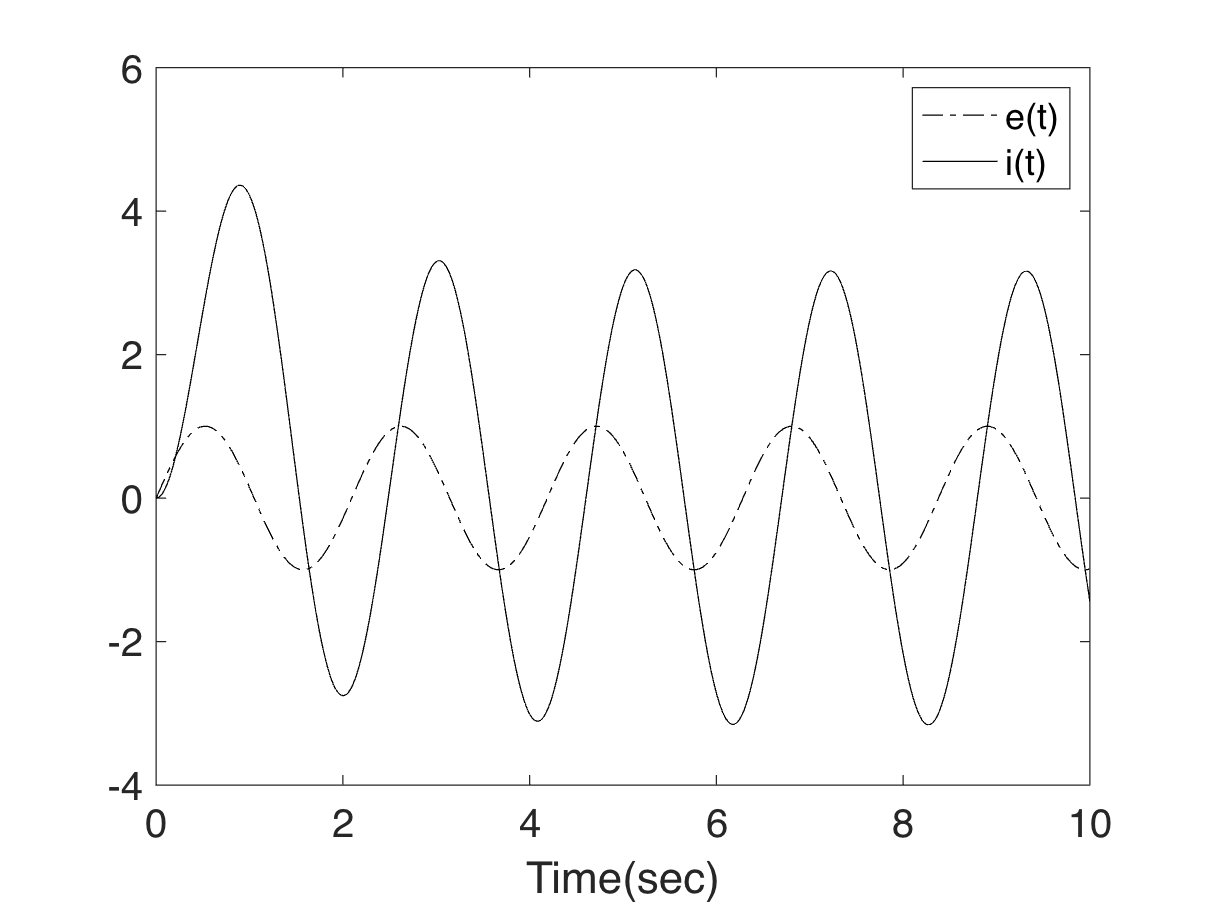

figure, box on, hold on;
plot(t,e,'k-.',t,i,'k-');
set(gca,'FontSize',16);
legend('e(t)','i(t)');
xlabel('Time(sec)');